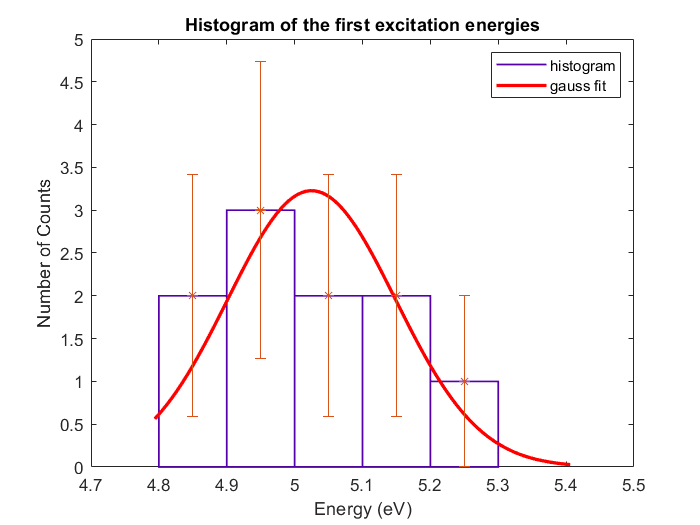


%CREATEFIT    Create plot of datasets and fits
%   PD1 = CREATEFIT(E)
%   Creates a plot, similar to the plot in the main distribution fitter
%   window, using the data that you provide as input.  You can
%   apply this function to the same data you used with dfittool
%   or with different data.  You may want to edit the function to
%   customize the code and this help message.
%
%   Number of datasets:  1
%   Number of fits:  1
%
%   See also FITDIST.

% This function was automatically generated on 03-May-2019 23:39:31

% Output fitted probablility distribution: PD1

% Data from dataset "E data":
%    Y = E

% Force all inputs to be column vectors
E = E(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "E data"
[CdfF,CdfX] = ecdf(E,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 5;
BinInfo.width = 0.1;
BinInfo.placementRule = 1;
[~,BinEdge] = internal.stats.histbins(E,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'E data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "fit 1"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('normal',[ 5.025, 0.1235808327461])
pd1 = fitdist(E, 'normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';

%%Errorbar
aa=[4.85 4.95 5.05 5.15 5.25];
bb=[2 3 2 2 1];
err=[2^(1/2) 3^(1/2) 2^(1/2) 2^(1/2) 1^(1/2)];
errorbar(aa,bb,err,'*')

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

legend({'histogram','gauss fit'},'Location','northeast')
title('Histogram of the first excitation energies')
xlabel('Energy (eV)')
ylabel('Number of Counts')




%%Mean:            5.025
%%Variance:        0.0152722
%  R-square: 0.7872